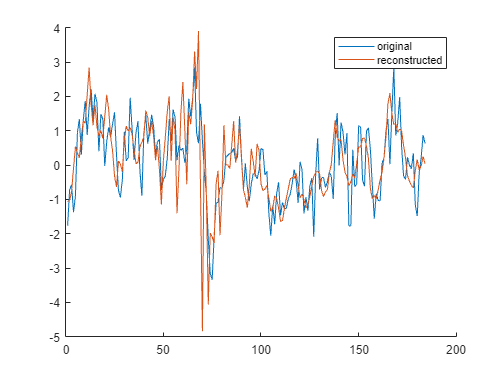

singal_idx = 7;
tmp_org = original(singal_idx,:,:);
tmp_rec = reconstr(singal_idx,:,:);

clf
hold on
plot(tmp_org(:), 'DisplayName', 'original')
plot(tmp_rec(:), 'DisplayName', 'reconstructed')
hold off
legend

## plot one channel's spectrum calculated from raw signals

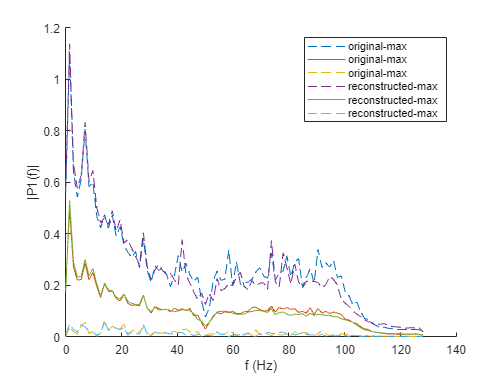

clf
plot_fft_stats_already_buffered(squeeze(original), 'original')
plot_fft_stats_already_buffered(squeeze(reconstr), 'reconstructed')

X = tmp;


function plot_fft_stats_already_buffered(X, name)
if nargin == 1
    name = '';
end
% X shape: (n_examples, n_timesamp)
Fs = 256;
L = 184; % adjust to signal length
BS = X;
for i = 1:size(BS, 1) % for all examples
    f = Fs*(0:(L/2))/L; % frequencies vector
    Y = fft(BS(i,:));
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    P1_all(i, :) = P1;
end
P1_means = mean(P1_all, 1);
P1_max = max(P1_all, [], 1);
P1_min = min(P1_all, [], 1);
hold on
plot(f, P1_max,'--','DisplayName', strcat([name, '-max']));
plot(f, P1_means, 'DisplayName', strcat([name, '-max']));
plot(f, P1_min,'--', 'DisplayName', strcat([name, '-max']));

hold off
xlabel("f (Hz)")
ylabel("|P1(f)|")
% legend(, strcat([gname, '-avg'], strcat([gname, '-min']))))
legend
end